t = readtable("step.tsv", "FileType","text",'Delimiter', '\t')

t = 1000001×9 table
     Time      Vs_pan     Vs_tilt     I_dot_pan    I_dot_tilt     I_pan     theta_dot_pan    I_tilt     theta_dot_tilt
    ______    ________    ________    _________    __________    _______    _____________    _______    ______________

         0           0           0           0             0           0            0              0            0     
    0.0009     4.1e-05       8e-06    0.011965      0.002462     1.1e-05            0          2e-06            0     
    0.0018     8.1e-05     1.7e-05     0.00144      0.000296     1.2e-05            0          2e-06            0     
    0.0027    0.000122     2.5e-05    0.010625      0.002128     2.2e-05      

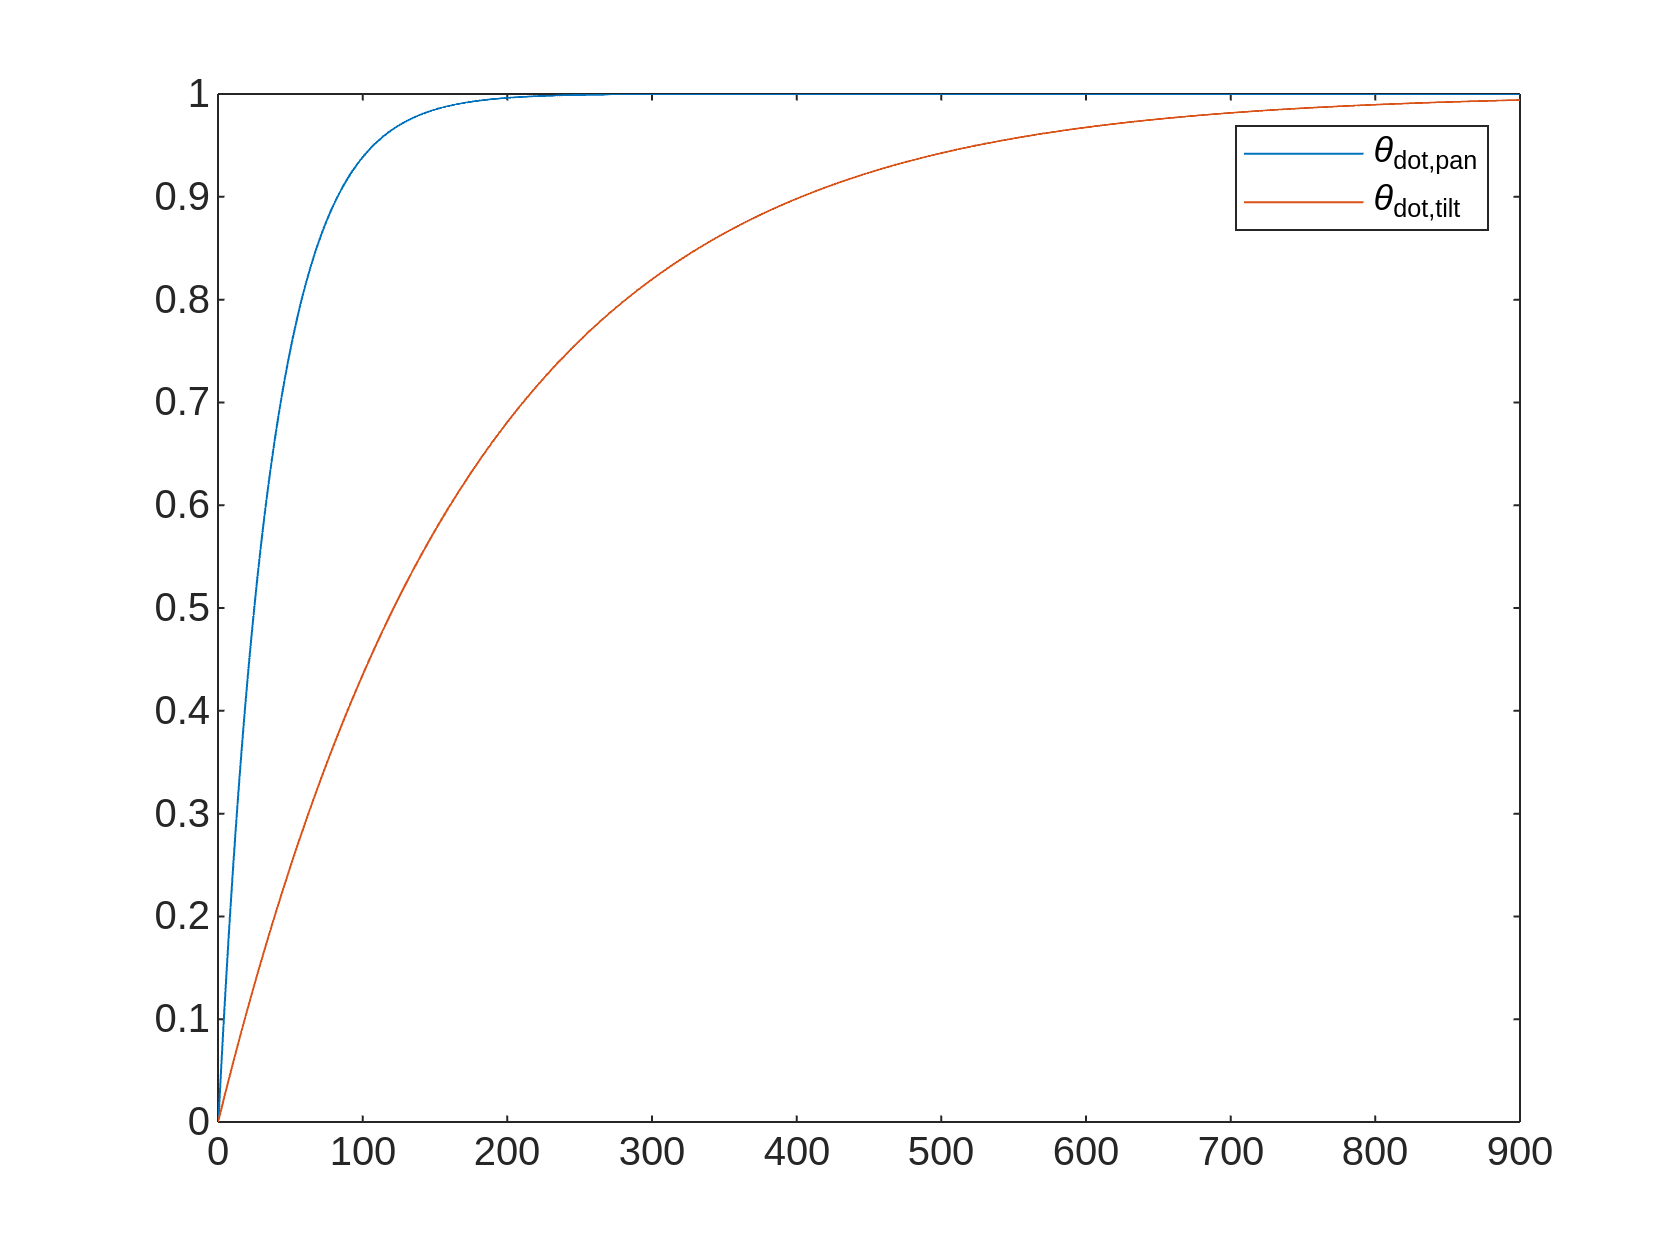

y = [
    t.theta_dot_pan'
    t.theta_dot_tilt'
];

u = [
    t.Vs_pan'
    t.Vs_tilt'
];

I = [
    t.I_pan'
    t.I_tilt'
];

I_dot = [
    t.I_dot_pan'
    t.I_dot_tilt'
];


plot(t.Time, y)
legend("\theta_{dot,pan}", "\theta_{dot,tilt}")

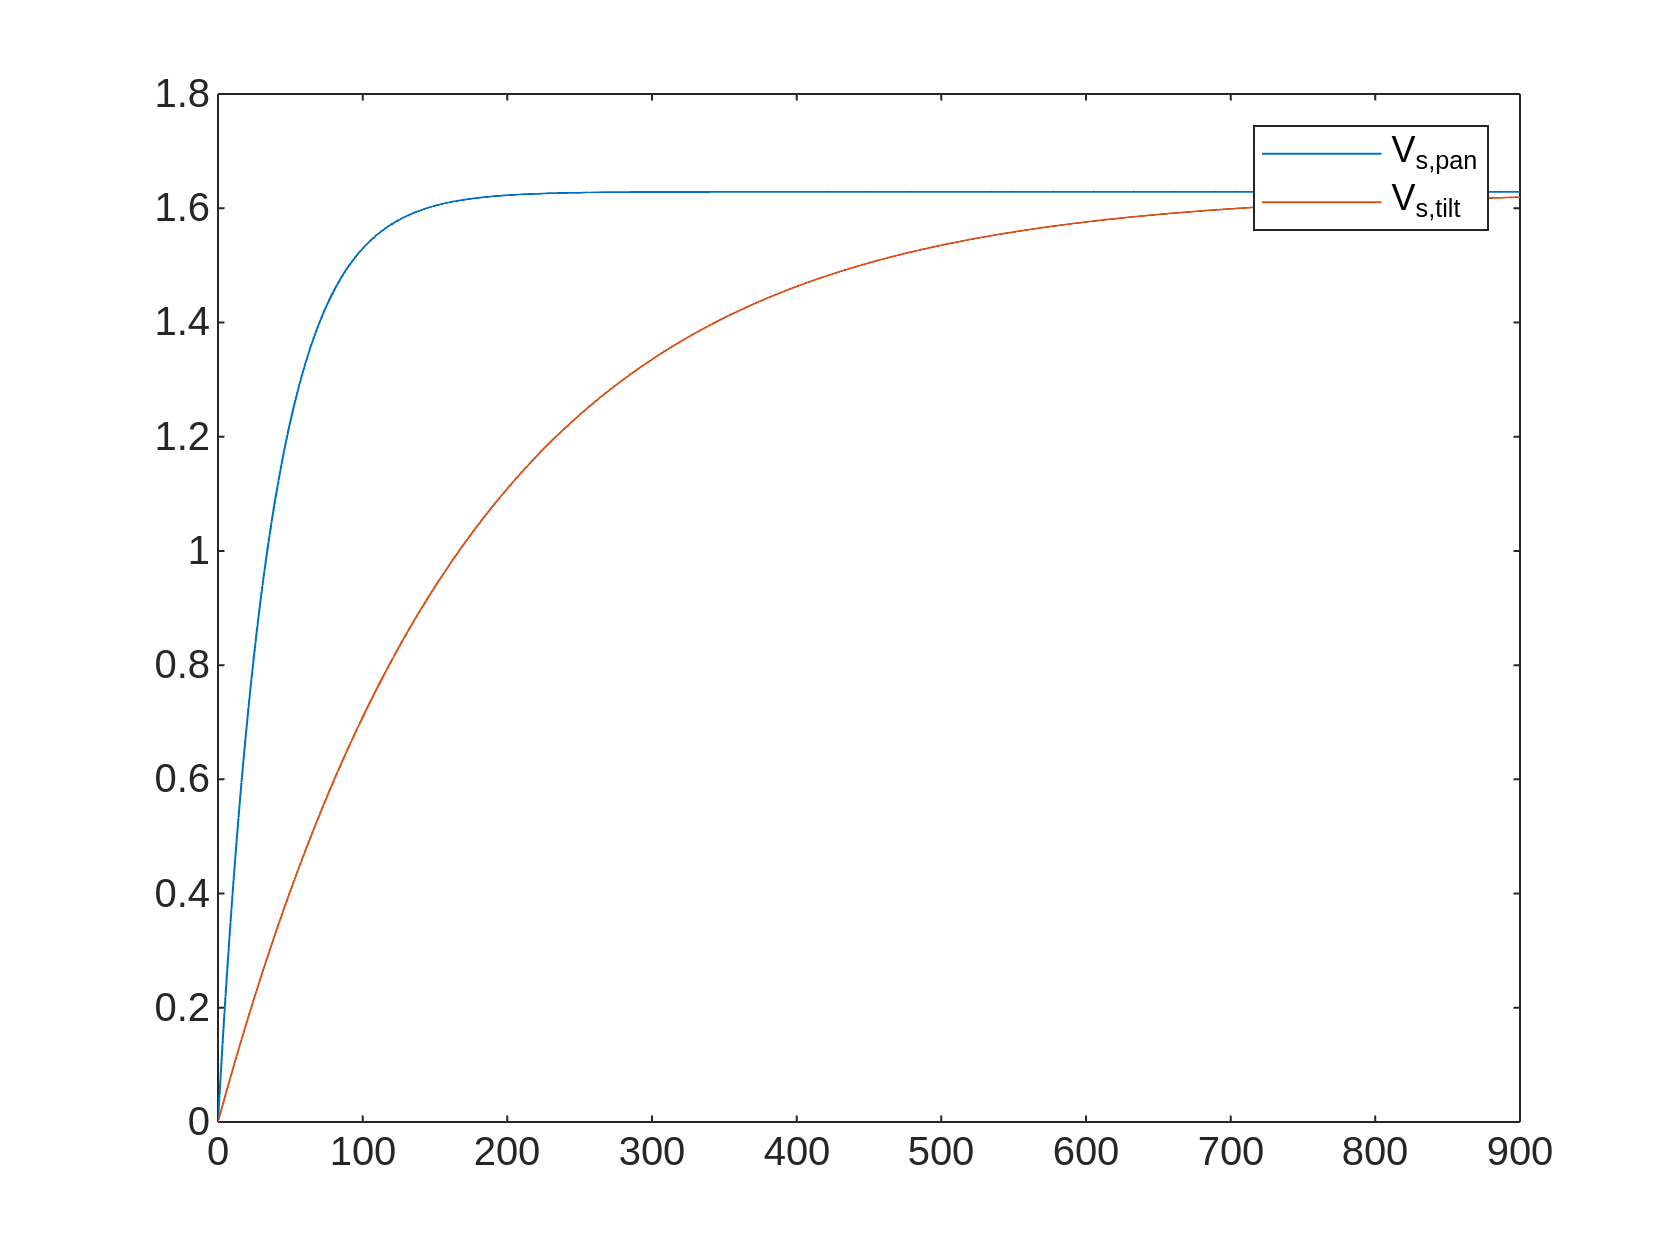

plot(t.Time, u)
legend("V_{s,pan}", "V_{s,tilt}")

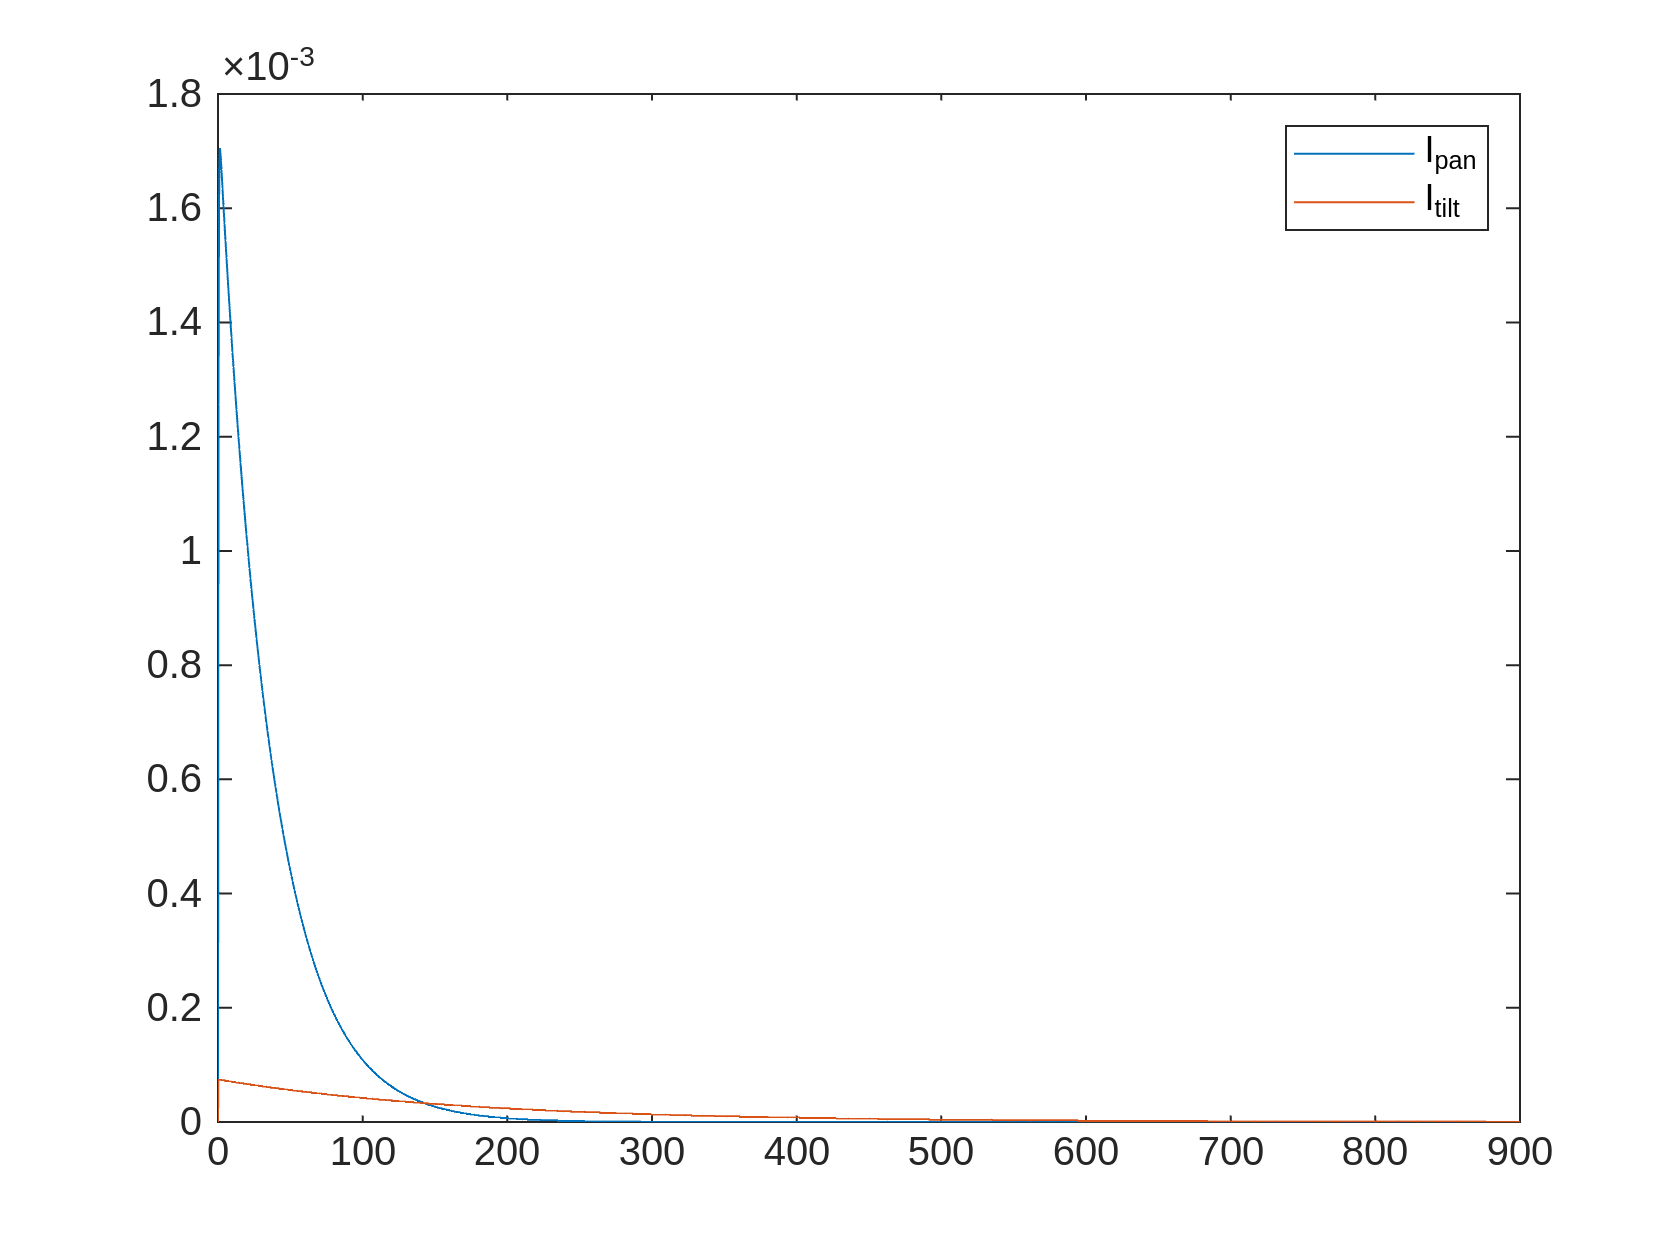


plot(t.Time, I)
legend("I_{pan}", "I_{tilt}")

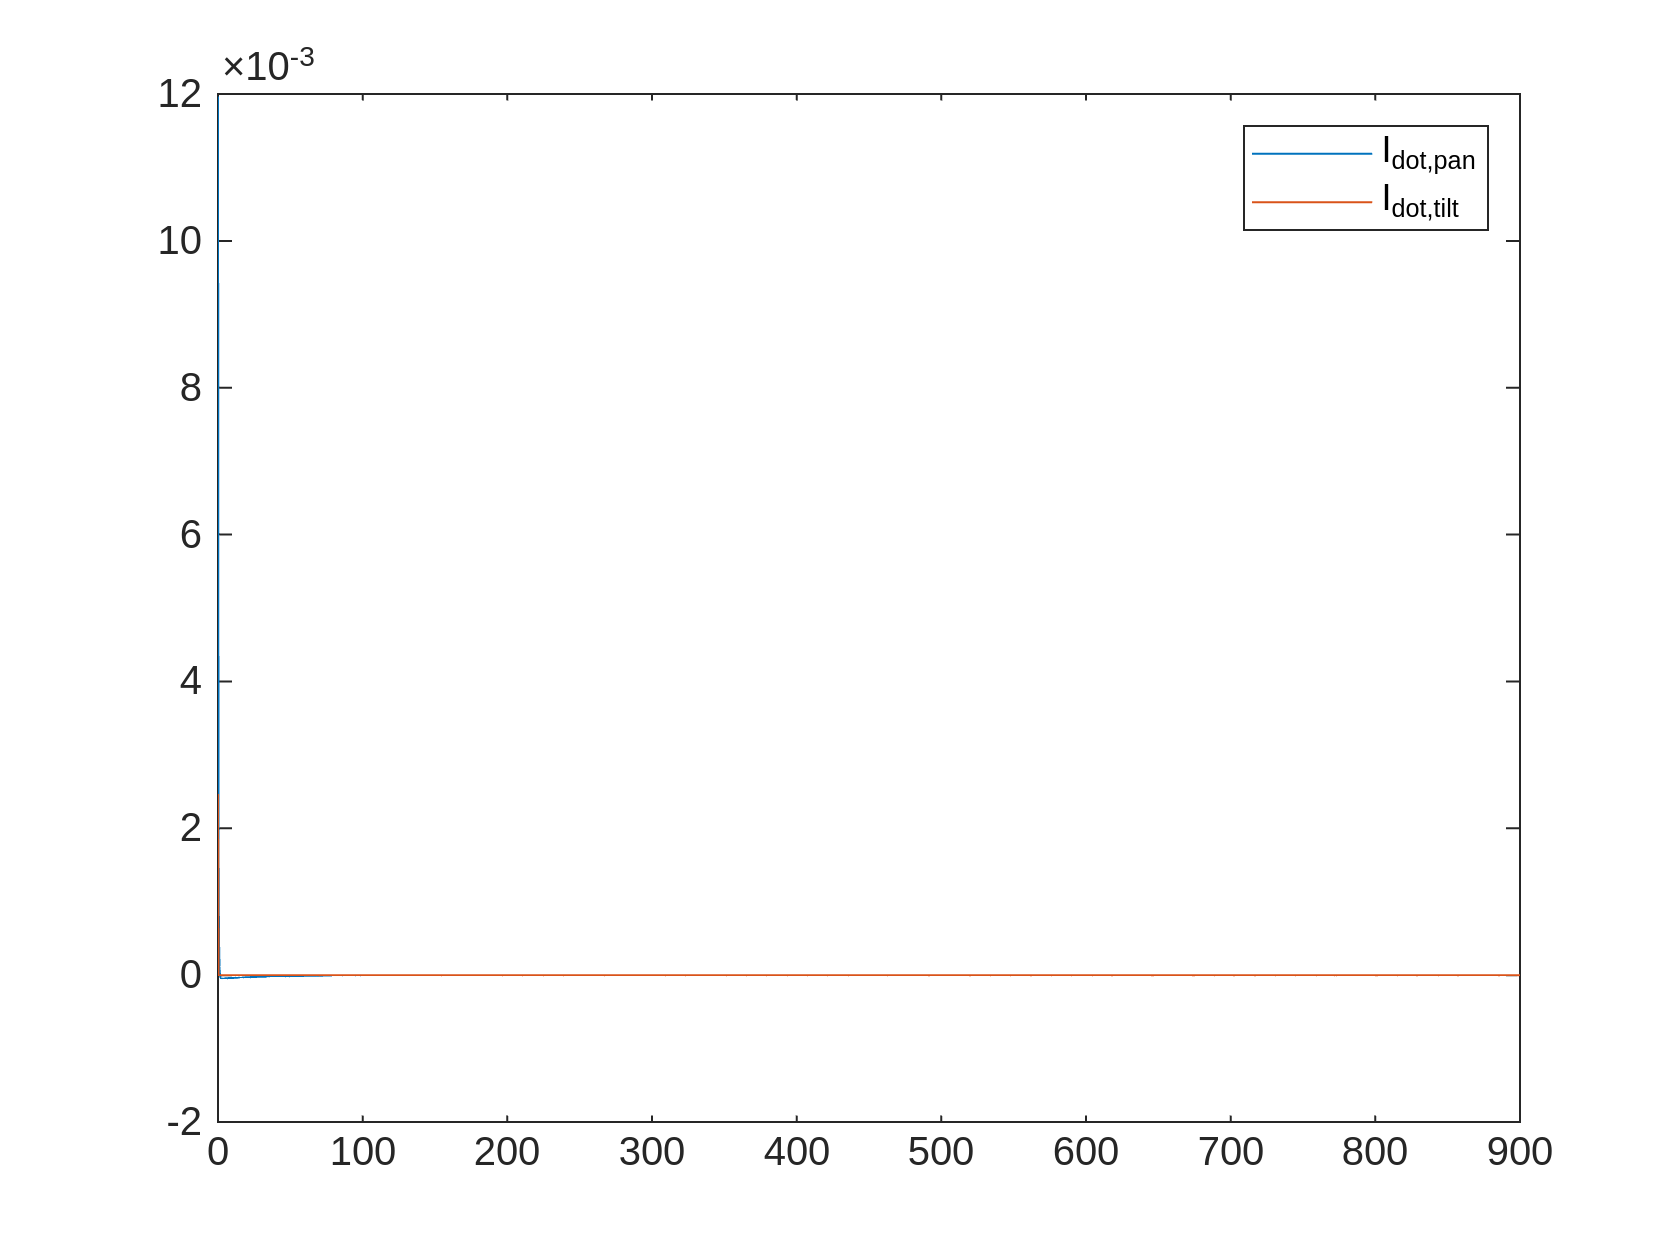


plot(t.Time, I_dot)
legend("I_{dot,pan}", "I_{dot,tilt}")